## Demonstration of Artificial Neural Networks

parts of the code taken from Matlab documentation

Copyright (C) by Ahmet Sacan

## Simple Classification Example

For a classification problem, you need to make sure you are using a network designed for classification tasks and you either get outputs that are already binary or that you can interpret them as binary.

% setup sample data for the AND problem.

%XT=[0 0 0; 1 0 0; 0 1 0; 1 1 1];
% setup sample data for XOR problem
XT=[0 0 0; 1 0 1; 0 1 1; 1 1 0];
X=XT(:,1:end-1); T=XT(:,end);
XT

XT =      0     0     0
     1     0     1
     0     1     1
     1     1     0


Create the network and configure the options.

%If this were a regression problem, we would have used  fitnet() to create
%the network. 
net=patternnet(1);
%net.trainParam.showWindow=0; %don't show the GUI window.

Let's force the network to not use validation and test sets

net.divideParam.trainRatio=1;
net.divideParam.valRatio=0;
net.divideParam.testRatio=0;

perform the training on the dataset. Matlab's neural network implmentation assumes samples are in columns and features are in rows. We transpose our dataset to conform to Matlab's convention for neural network data.

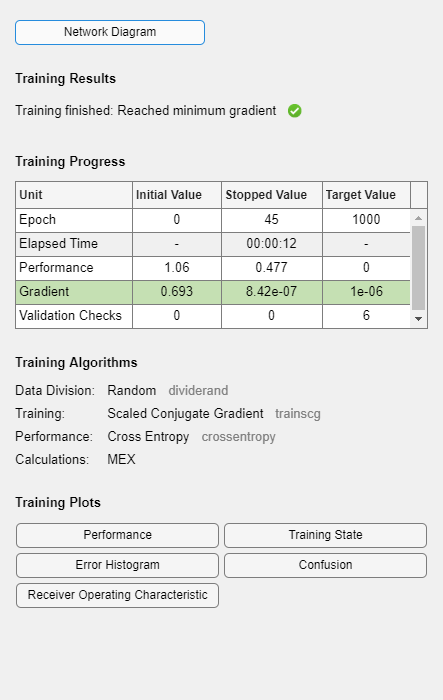

net = train(net,X',T');

### Test the network performance.

Here, I am just calculating the "training" performance. For a proper evaluation, you would need to report performance on a separate "test" set and/or perform cross-validation.

Y = sim(net, X')';

% You need to examine target and network output values to make sure you are
% comparing them correctly. Here, targets are 0 or 1; and the network
% output is a continuous value between 0 and 1. I am thresholding network's
% output Y, to convert it to 0 or 1 and use that as a classification decision.
cp = classperf(T, Y>0.5);

% I'll report accuracy here. You may also need to report sensitivity &
% specificity for a more comprehensive reporting of the performance.
accuracy = cp.CorrectRate

accuracy = 0.7500

## Neural Network Regression

For a regression problem, you need to make sure you are using a network designed to produce real-valued outputs.

#### Setup the data for house dataset

% house_dataset (your version of Matlab may not have this dataset) contains
% information about 506 real estate properties, and their relative valuation.
load house_dataset
X=houseInputs';
T=houseTargets';	

I will use only the first "fold". For a proper implementation, you need to repeat the training & evaluation on all folds and report the averaage performance on these test sets.

Icross = crossvalind('kfold',size(X,1),4);
Itest = Icross == 1;


%%
Xtest = X(Itest, :);
Ttest = T(Itest);
Xtrain = X(~Itest, :);
Ttrain = T(~Itest);

Create a network with 1 neuron in one hidden layer.

net=fitnet(1); %notice we are using fitnet() for regression problems, instead of patternet.

%net.trainParam.showWindow=0; %don't show the GUI window.
% Let's force the network to not use validation and test sets
net.divideParam.trainRatio=1;
net.divideParam.valRatio=0;
net.divideParam.testRatio=0;

train the network

net=train(net,Xtrain',Ttrain');

Evaluate the network performance on the test set.

Ytest = sim(net, Xtest')';

% For regression problems, Mean-squared-error is the appropriate
% performance metric.
mse = sqrt( immse(Ytest,Ttest) )

mse = 4.0447



% Also see: nftool() for a Graphical tool to construct & train Neural
% Networks.